initAnymalParam

initializeRobotParameters


mdl = 'rlQuadruped';
open_system(mdl);

Model 'rlQuadruped' was created with a newer version (R2020b) of Simulink
To disable this error message, use Simulink preferences.
To create a model that is compatible with this version of Simulink, load the model in Simulink R2020b and select Save > Export Model to > Previous Version.


numObs = 56;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

numAct = 12;
actInfo = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit', 1);
actInfo.Name = 'torque';

blk = [mdl, '/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

env.ResetFcn = @quadrupedResetFcn;

agent = createDDPGAgent(numObs,obsInfo,numAct,actInfo,Ts);

% value limit for torque commands
u_max = 25;  % Nm

maxEpisodes = 30000;
maxSteps = floor(Tf/Ts);  
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',250,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',190,...                   
    'SaveAgentCriteria','EpisodeReward',... 
    'SaveAgentValue',200);  

trainOpts.UseParallel = false;                    
trainOpts.ParallelizationOptions.Mode = 'async';
trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';

doTraining = false;
if doTraining    
    % Train the agent
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example
    load('savedAgents\DDPGAgent_2ndRound.mat')
end

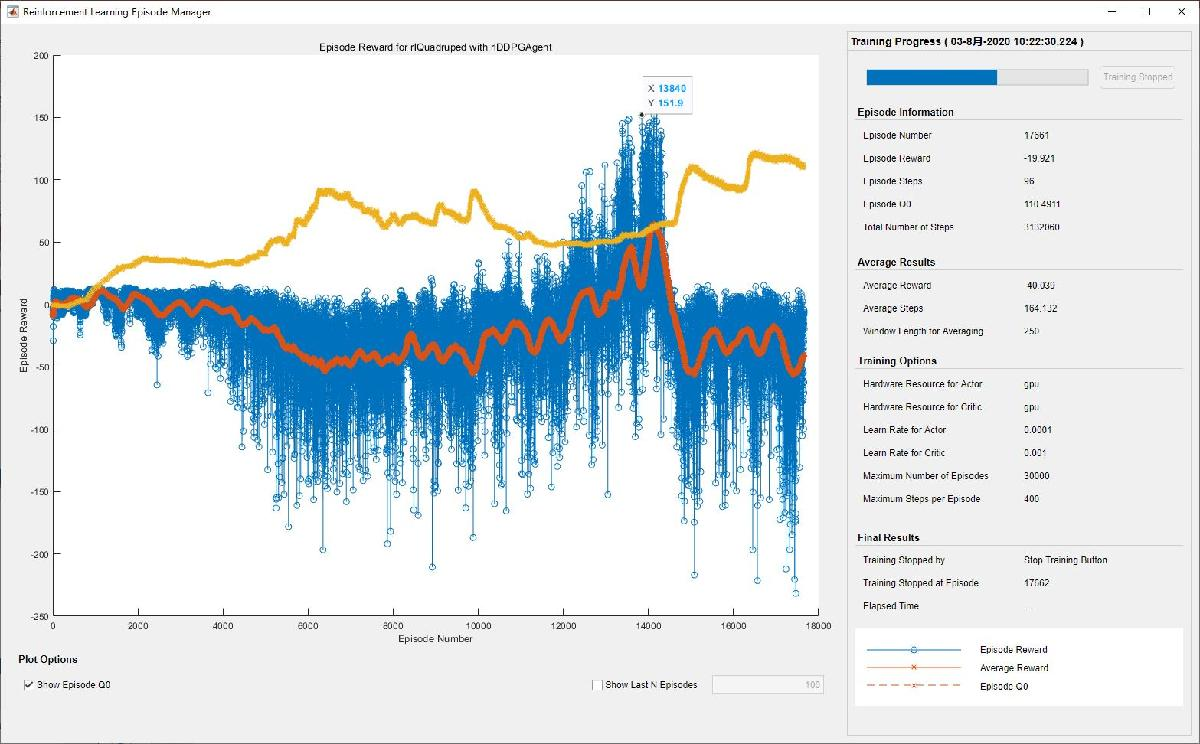

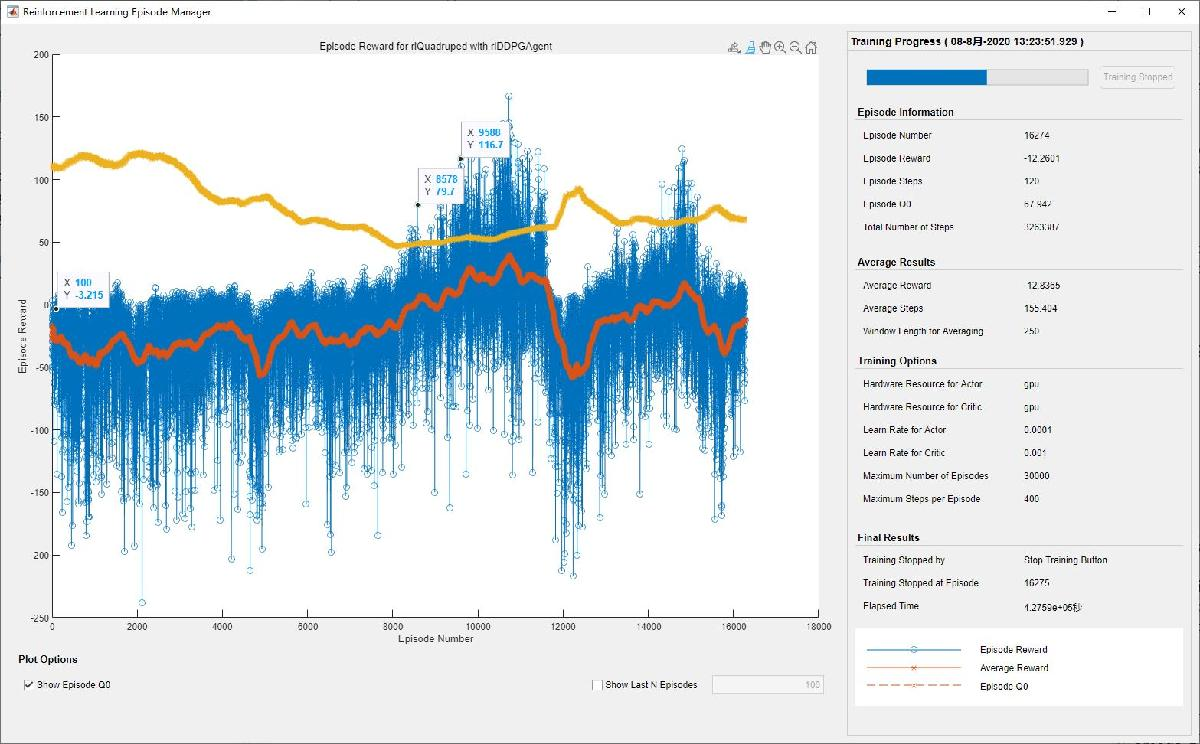

rng(0)

simOptions = rlSimulationOptions('MaxSteps',maxSteps);
experience = sim(env,agent,simOptions);